# Activity 4: Modulation Transfer Function Extra Work

#### Submitted by: Jonabel Eleanor B. Baldres

#### Applied Physics 167 THU

% Load the image and display it in RGB
image = imread('result_ECC.jpg');
figure;
imshow(image);
title('Original Image');

% Capture the intensity profile using improfile()
profile = improfile();
close;

% Select the dimensions of the RGB channels
R = profile(:, :, 1);
G = profile(:, :, 2);
B = profile(:, :, 3);

% Calculate the derivative of each channel 
derivativeR = diff(R);
derivativeG = diff(G);
derivativeB = diff(B);

%FFT

fftR = abs(fft(derivativeR));
fftG = abs(fft(derivativeG));
fftB = abs(fft(derivativeB)) ; 

%Calibration
%Red
MTF_r = fftR/max(fftR);
dx_r = 1/35; 
N_r = length(MTF_r);
x_r = 0:dx_r:(N_r-1)*dx_r; 
Fmax_r = 1/(2*dx_r);
df_r = 1/((N_r-1)*dx_r);
K_r = round(N_r/2); 
f_r = 0:df_r:Fmax_r;

%Green
MTF_g = fftG/max(fftG);
dx_g = 1/35; 
N_g = length(MTF_g);
x_g = 0:dx_g:(N_g-1)*dx_g; 
Fmax_g = 1/(2*dx_g);
df_g = 1/((N_g-1)*dx_g);
K_g = round(N_r/2); 
f_g = 0:df_g:Fmax_g;

%Blue
MTF_b = fftB/max(fftB);
dx_b = 1/35; 
N_b = length(MTF_b);
x_b = 0:dx_b:(N_b-1)*dx_b; 
Fmax_b = 1/(2*dx_b);
df_b = 1/((N_b-1)*dx_b);
K_b = round(N_b/2); 
f_b = 0:df_b:Fmax_b;

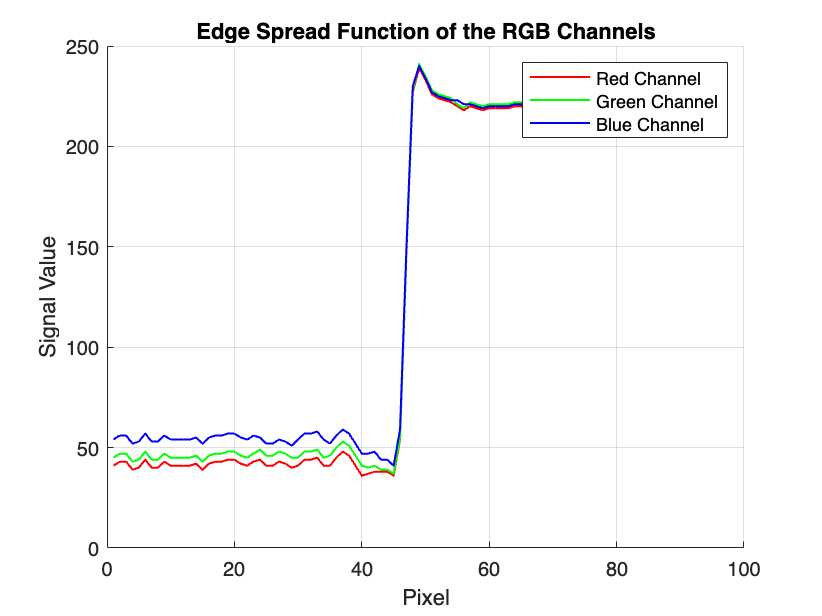

% Edge Spread Function
figure;
hold on;
plot(R, 'r',LineWidth=1);
plot(G, 'g',LineWidth=1);
plot(B, 'b',LineWidth=1);
title('Edge Spread Function of the RGB Channels');
ylabel('Signal Value')
xlabel('Pixel')
legend('Red Channel', 'Green Channel', 'Blue Channel');
grid on;
hold off;
saveas(gcf, 'edge_spread_extra.png');

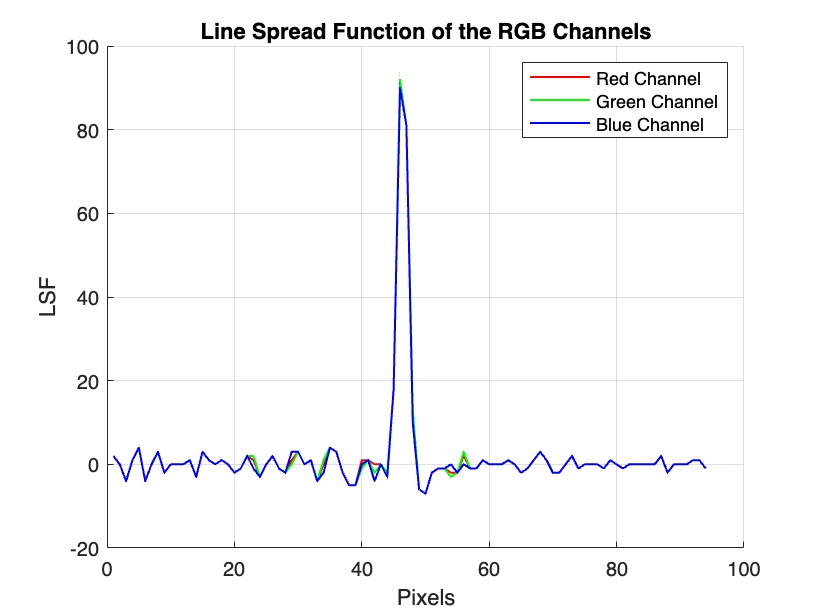

% Line Spread Function
figure;
hold on;
plot(derivativeR, 'r',LineWidth=1);
plot(derivativeG, 'g',LineWidth=1);
plot(derivativeB, 'b',LineWidth=1);
title('Line Spread Function of the RGB Channels');
legend('Red Channel', 'Green Channel', 'Blue Channel');
xlabel('Pixels');
ylabel('LSF');
grid on;
hold off;
saveas(gcf, 'line_spread_extra.png');

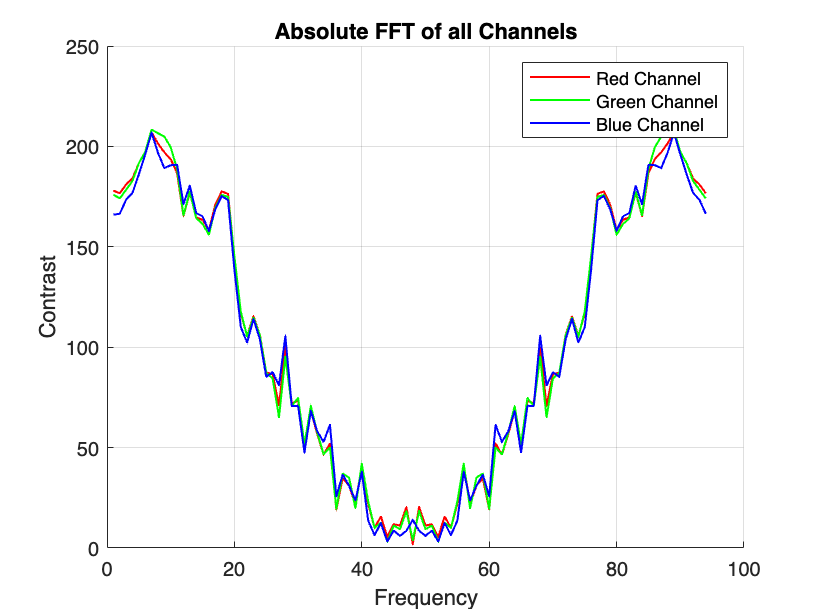

% Absolute FFT
figure;
hold on;
plot(fftR, 'r', LineWidth = 1);
plot(fftG, 'g', LineWidth = 1);
plot(fftB, 'b', LineWidth = 1);
title('Absolute FFT of all Channels');
legend('Red Channel', 'Green Channel', 'Blue Channel');
xlabel('Frequency');
ylabel('Contrast')
grid on;
hold off;
saveas(gcf, 'FFT_extra.png');

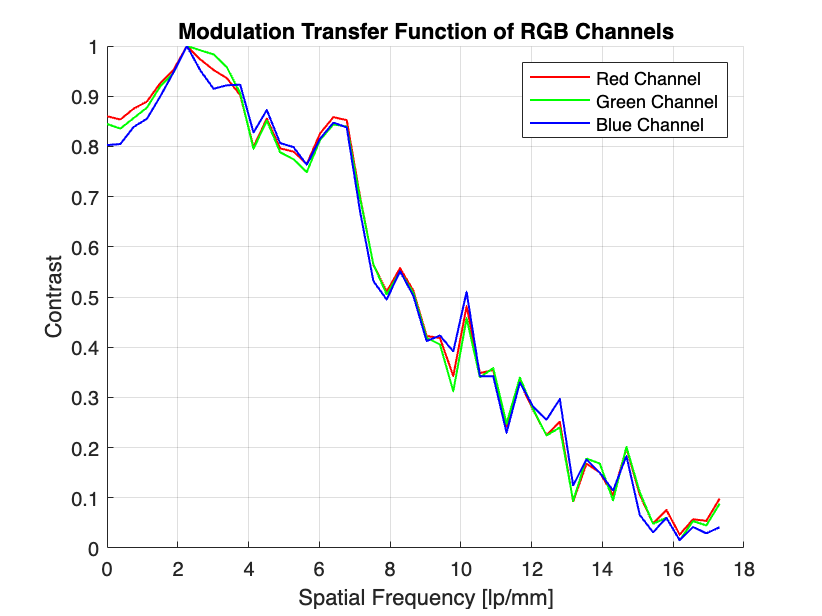

% Modulation Transfer Function
figure;
hold on; 
plot(f_r, MTF_r(1:K_r), 'r', LineWidth=1);
plot(f_g, MTF_g(1:K_g), 'g', LineWidth=1);
plot(f_b, MTF_b(1:K_b), 'b', LineWidth=1);
title('Modulation Transfer Function of RGB Channels');
legend('Red Channel', 'Green Channel', 'Blue Channel');
xlabel('Spatial Frequency [lp/mm]');
ylabel('Contrast')
grid on;
hold off;
saveas(gcf, 'MTF_extra.png');